# 7. Modelo Geométrico Directo.

- Halle el modelo geométrico directo de su robot asignado usando MTH.

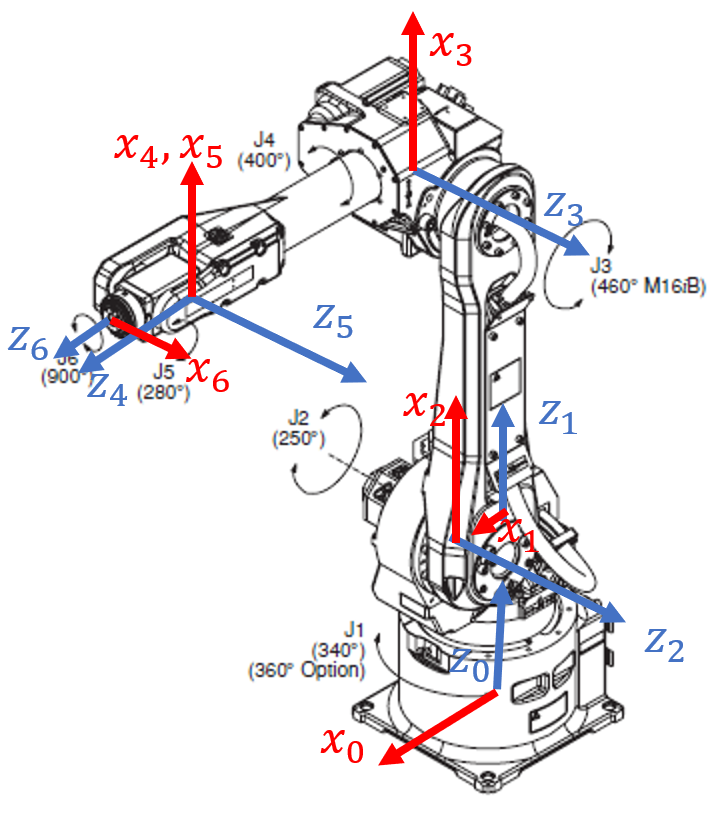

Figura 1. Diagrama para determinar parámetros de DH mod. 

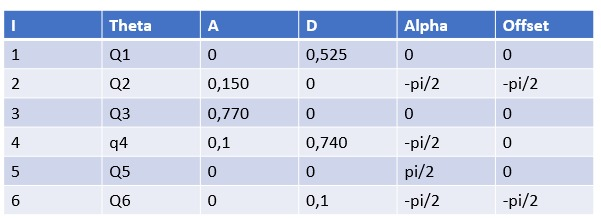

Tabla 1. Parámetros de DH mod.

clear;
clc;
syms q1 q2 q3 q4 q5 q6
T01 = trotx(0)*transl(0,0,0.525)*trotz(q1);
T12 = trotx(-pi/2)*transl(0.15,0,0)*trotz(q2-pi/2);
T23 = trotx(0)*transl(0.77,0,0)*trotz(q3);
T34 = trotx(-pi/2)*transl(0.1,0,0.740)*trotz(q4);
T45 = trotx(pi/2)*transl(0,0,0)*trotz(q5);
T56 = trotx(-pi/2)*transl(0,0,0.1)*trotz(q6-pi/2);
T6NOA = trotz(0)*transl(0,0,0)*trotx(0);

% Modelo geométrico directo
M0NOA=T01*T12*T23*T34*T45*T56*T6NOA;

2. Haciendo uso del modelo cinemático directo obtenga los valores de posición y de orientación en coordenadas generalizadas del efector final de su robot asignado para los siguientes valores articulares: 

% Configuración de articulaciones 1
q=[0.5, 0.2, 0.4, 0.5, 0, 1.5];
q1=q(1);
q2=q(2);
q3=q(3);
q4=q(4);
q5=q(5);
q6=q(6);
M0NOA_1=eval(M0NOA);
xyz1=M0NOA_1(1:3,4)

xyz1 =     0.9239
    0.5047
    0.8879


rpy1=tr2rpy(M0NOA_1)

rpy1 =    -2.5303    0.8100   -0.3397



% Configuración de articulaciones 2
q=[-pi/2,0.3,0,pi/2,0.4,1.2];
q1=q(1);
q2=q(2);
q3=q(3);
q4=q(4);
q5=q(5);
q6=q(6);
M0NOA_2=eval(M0NOA);
xyz2=M0NOA_2(1:3,4)

xyz2 =     0.0389
   -1.2020
    1.1102


rpy2=tr2rpy(M0NOA_2)

rpy2 =     1.8708    0.4000    2.7708



% Configuración de articulaciones 3
q=[0,1,-0.5,2,1,0.5];
q1=q(1);
q2=q(2);
q3=q(3);
q4=q(4);
q5=q(5);
q6=q(6);
M0NOA_3=eval(M0NOA);
xyz3=M0NOA_3(1:3,4)

xyz3 =     1.5595
    0.0765
    0.6788


rpy3=tr2rpy(M0NOA_3)

rpy3 =    -1.5078    0.6972   -0.4660



% Configuración de articulaciones 4
q=[-1,-0.3,-pi/5,0.4,0.2,1];
q1=q(1);
q2=q(2);
q3=q(3);
q4=q(4);
q5=q(5);
q6=q(6);
M0NOA_4=eval(M0NOA);
xyz4=M0NOA_4(1:3,4)

xyz4 =     0.2006
   -0.2980
    1.9805


rpy4=tr2rpy(M0NOA_4)

rpy4 =     0.7061    0.4797    1.8179


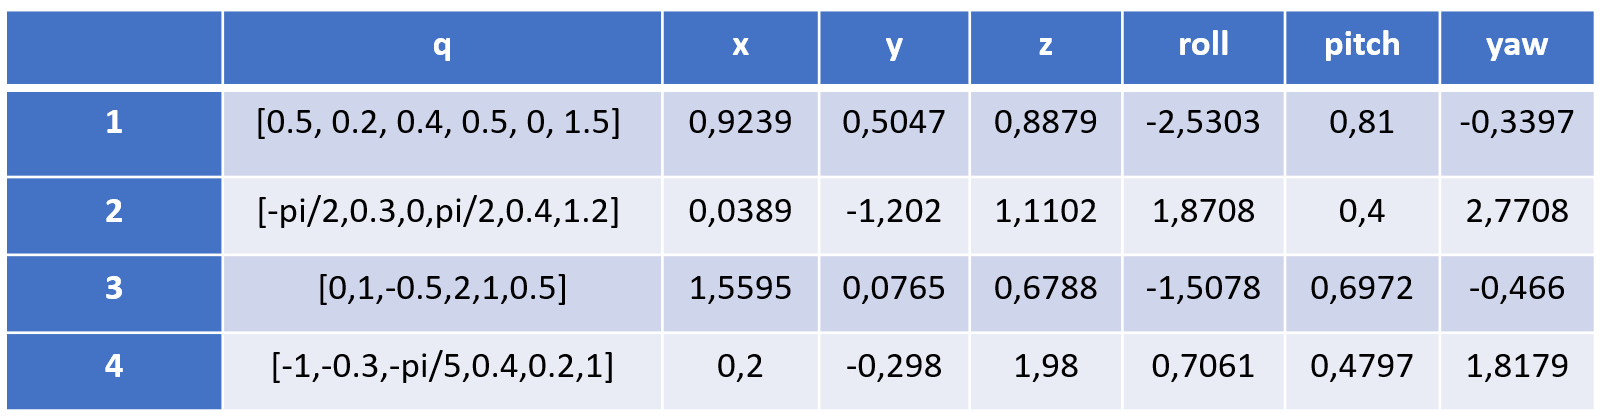

Tabla 2. Posición y orientación de las configuraciones de articulaciones de prueba.

3. Haga uso de las funciones de cinemática directa de ambos toolboxes y compruebe los resultados anteriores.

Peter Corke Toolbox

clc;
clear;
ws = [-70 50 -30 30 -40 40]/10;
plot_options={'workspace',ws,'scale',.5,'view',[125,25],'noa','jaxes','tilesize',2,'ortho', 'lightpos',[2 2 10]};

L(1) = Link('revolute' ,'alpha',0,    'a', 0.000,'d',0.525,'offset', 0,    'modified');
L(2) = Link('revolute' ,'alpha',-pi/2,'a', 0.150,'d',0.000,'offset', -pi/2,'modified');
L(3) = Link('revolute' ,'alpha',0,    'a', 0.770,'d',0.000,'offset', 0,    'modified' );
L(4) = Link('revolute' ,'alpha',-pi/2,'a', 0.100,'d',0.740,'offset', 0,'modified');
L(5) = Link('revolute' ,'alpha',pi/2 ,'a', 0.000,'d',0.000,'offset', 0, 'modified');
L(6) = Link('revolute' ,'alpha',-pi/2,'a', 0.000,'d',0.100,'offset', -pi/2,'modified');
Robot = SerialLink(L,'name','Robot_{RRRRRR}','plotopt',plot_options);
Robot.tool= trotz(0)*transl(0,0,0)*trotx(0)

 
Robot = 
 
Robot_{RRRRRR} (6 axis, RRRRRR, modDH, fastRNE)                  
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|      0.525|          0|          0|          0|
|  2|         q2|          0|       0.15|     -1.571|     -1.571|
|  3|         q3|          0|       0.77|          0|          0|
|  4|         q4|       0.74|        0.1|     -1.571|          0|
|  5|         q5|          0|          0|      1.571|          0|
|  6|         q6|        0.1|          0|     -1.571|     -1.571|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0            

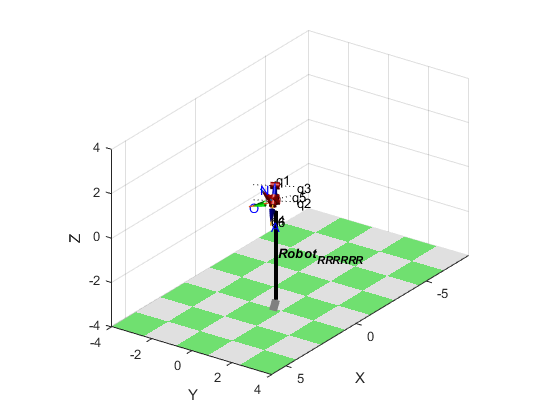

syms q1 q2 q3 q4 q5 q6

q1=[0.5, 0.2, 0.4, 0.5, 0, 1.5];
q2=[-pi/2,0.3,0,pi/2,0.4,1.2];
q3=[0,1,-0.5,2,1,0.5];
q4=[-1,-0.3,-pi/5,0.4,0.2,1];

TPK_1 = Robot.fkine(q1);
Robot.plot(q1);

xyz1=TPK_1(1:3,4)

xyz1 =     0.9239
    0.5047
    0.8879


rpy1=tr2rpy(TPK_1)

rpy1 =    -2.5303    0.8100   -0.3397


TPK_2 = Robot.fkine(q2);
xyz2=TPK_2(1:3,4)

xyz2 =     0.0389
   -1.2020
    1.1102


rpy2=tr2rpy(TPK_2)

rpy2 =     1.8708    0.4000    2.7708


TPK_3 = Robot.fkine(q3);
xyz3=TPK_3(1:3,4)

xyz3 =     1.5595
    0.0765
    0.6788


rpy3=tr2rpy(TPK_3)

rpy3 =    -1.5078    0.6972   -0.4660


TPK_4 = Robot.fkine(q4);
xyz4=TPK_4(1:3,4)

xyz4 =     0.2006
   -0.2980
    1.9805


rpy4=tr2rpy(TPK_4)

rpy4 =     0.7061    0.4797    1.8179


Robotics Systems Toolbox

body1=rigidBody('body1');
jnt1 = rigidBodyJoint('jnt1','revolute');
jnt1.HomePosition = 0;
tform = trvec2tform([0, 0, 0.525]); % User defined
setFixedTransform(jnt1,tform);
body1.Joint = jnt1;
robot = rigidBodyTree;
addBody(robot,body1,'base');
body2 = rigidBody('body2');
jnt2 = rigidBodyJoint('jnt2','revolute');
jnt2.HomePosition = 0; % User defined
tform2 = trvec2tform([0.15, 0, 0])*eul2tform([0, -pi/2, -pi/2]); % User defined
setFixedTransform(jnt2,tform2);
body2.Joint = jnt2;
addBody(robot,body2,'body1'); % Add body2 to body1
body3 = rigidBody('body3');
jnt3 = rigidBodyJoint('jnt3','revolute');
jnt3.HomePosition = 0; % User defined
tform3 = trvec2tform([0.77, 0, 0]); % User defined
setFixedTransform(jnt3,tform3);
body3.Joint = jnt3;
addBody(robot,body3,'body2'); % Add body3 to body2
body4 = rigidBody('body4');
jnt4 = rigidBodyJoint('jnt4','revolute');
jnt4.HomePosition = 0; % User defined
tform4 = trvec2tform([0.1, 0.74, 0])*eul2tform([0, 0, -pi/2]); % User defined
setFixedTransform(jnt4,tform4);
body4.Joint = jnt4;
addBody(robot,body4,'body3'); % Add body4 to body3
body5 = rigidBody('body5');
jnt5 = rigidBodyJoint('jnt5','revolute');
jnt5.HomePosition = 0; % User defined
tform5 = trvec2tform([0, 0, 0])*eul2tform([0, 0, pi/2]); % User defined
setFixedTransform(jnt5,tform5);
body5.Joint = jnt5;
addBody(robot,body5,'body4'); % Add body5 to body4
body6 = rigidBody('body6');
jnt6 = rigidBodyJoint('jnt6','revolute');
jnt6.HomePosition = 0; % User defined
tform6 = trvec2tform([0, 0.1, 0])*eul2tform([0, -pi/2, -pi/2]); % User defined
setFixedTransform(jnt6,tform6);
body6.Joint = jnt6;
addBody(robot,body6,'body5'); % Add body6 to body5
Tool = rigidBody('Tool');
jnt7 = rigidBodyJoint('jnt7','fixed');
tform7 = trvec2tform([0, 0, 0]); % User defined
setFixedTransform(jnt7,tform7);
Tool.Joint = jnt7;
addBody(robot,Tool,'body6'); % Add Tool to body6
show(robot)

ans =   Axes (Primary) with properties:

             XLim: [-2.5000 2.5000]
             YLim: [-2.5000 2.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


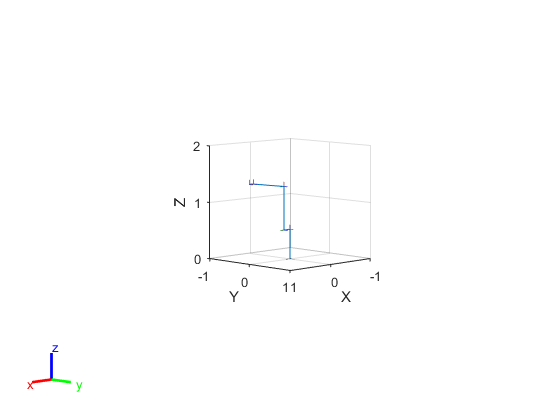

xlim([-1.00 1.00])
ylim([-1.00 1.00])
zlim([-0.0 2.00])

config = homeConfiguration(robot);
config(1).JointPosition=q1(1);
config(2).JointPosition=q1(2);
config(3).JointPosition=q1(3);
config(4).JointPosition=q1(4);
config(5).JointPosition=q1(5);
config(6).JointPosition=q1(6);
TRST_1=getTransform(robot,config,'Tool','base');
config(1).JointPosition=q2(1);
config(2).JointPosition=q2(2);
config(3).JointPosition=q2(3);
config(4).JointPosition=q2(4);
config(5).JointPosition=q2(5);
config(6).JointPosition=q2(6);
TRST_2=getTransform(robot,config,'Tool','base');
config(1).JointPosition=q3(1);
config(2).JointPosition=q3(2);
config(3).JointPosition=q3(3);
config(4).JointPosition=q3(4);
config(5).JointPosition=q3(5);
config(6).JointPosition=q3(6);
TRST_3=getTransform(robot,config,'Tool','base');
config(1).JointPosition=q4(1);
config(2).JointPosition=q4(2);
config(3).JointPosition=q4(3);
config(4).JointPosition=q4(4);
config(5).JointPosition=q4(5);
config(6).JointPosition=q4(6);
TRST_4=getTransform(robot,config,'Tool','base');

xyz1=TRST_1(1:3,4)

xyz1 =     0.9239
    0.5047
    0.8879


rpy1=tr2rpy(TRST_1)

rpy1 =    -2.5303    0.8100   -0.3397


xyz2=TRST_2(1:3,4)

xyz2 =     0.0389
   -1.2020
    1.1102


rpy2=tr2rpy(TRST_2)

rpy2 =     1.8708    0.4000    2.7708


xyz3=TRST_3(1:3,4)

xyz3 =     1.5595
    0.0765
    0.6788


rpy3=tr2rpy(TRST_3)

rpy3 =    -1.5078    0.6972   -0.4660


xyz4=TRST_4(1:3,4)

xyz4 =     0.2006
   -0.2980
    1.9805


rpy4=tr2rpy(TRST_4)

rpy4 =     0.7061    0.4797    1.8179


4.  Compare los métodos.

Como era de esperarse, con los tres métodos se obtiene el mismo resultado. Sin embargo, cabe resaltar que el método de cinemática geométrica directa por MTH y en el método del toolbox RVC se utilizan los parámetros de DH mod, que para el caso del RST no son necesarios. 

Los tres métodos se diferencian en la contrucción que cada uno realiza para el robot:

El método de la cinemática geométrica directa por MTH, es más un método que parte de un análisis gráfico para luego realizar uno algebráico que relaciona las MTH que componen a un robot.

El método de RVC construye todos los eslabones del robot por medio de los parámetros de DH mod, añadiendo de manera inmediata tanto eslabón como restricción de movimiento del mismo (tipo de articulación), sin embargo, estos eslabones se manejan únicamente en cadena.

El principal añadido del RST frente al RVC es que es posible crear cuerpos rígidos y realizar una configuración de eslabones en forma de árbol, de tal manera que un eslabón se puede conectar con varios a la vez.

5. Elija uno de los métodos anteriormente usados y desarrolle una GUI que permita mover cada articulación mediante controles tipo Slider, visualizar el robot y la posición del efector final.

La GUI se encuentra en el archivo: appLab2.

6. En el informe incluya capturas de pantalla verificando las posiciones EF y las articulaciones.

Para efectos prácticos se realiza la verificación con las configuraciones articulares del inciso 2:

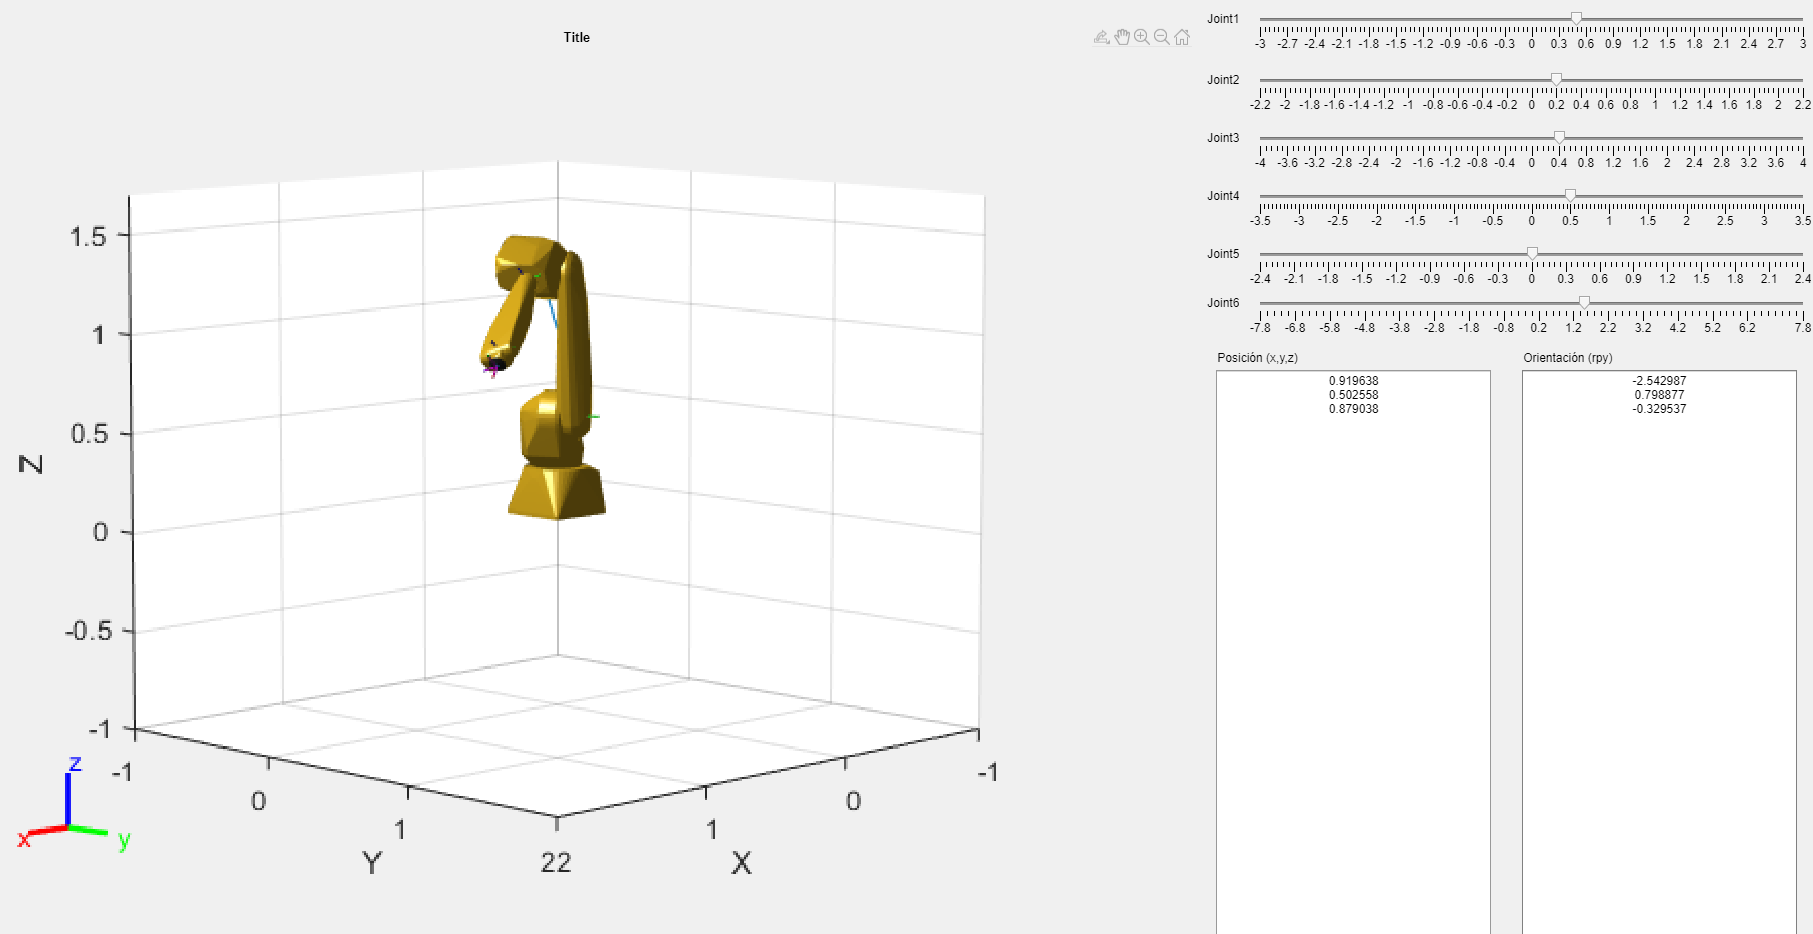

Figura 2. Verificación punto 1

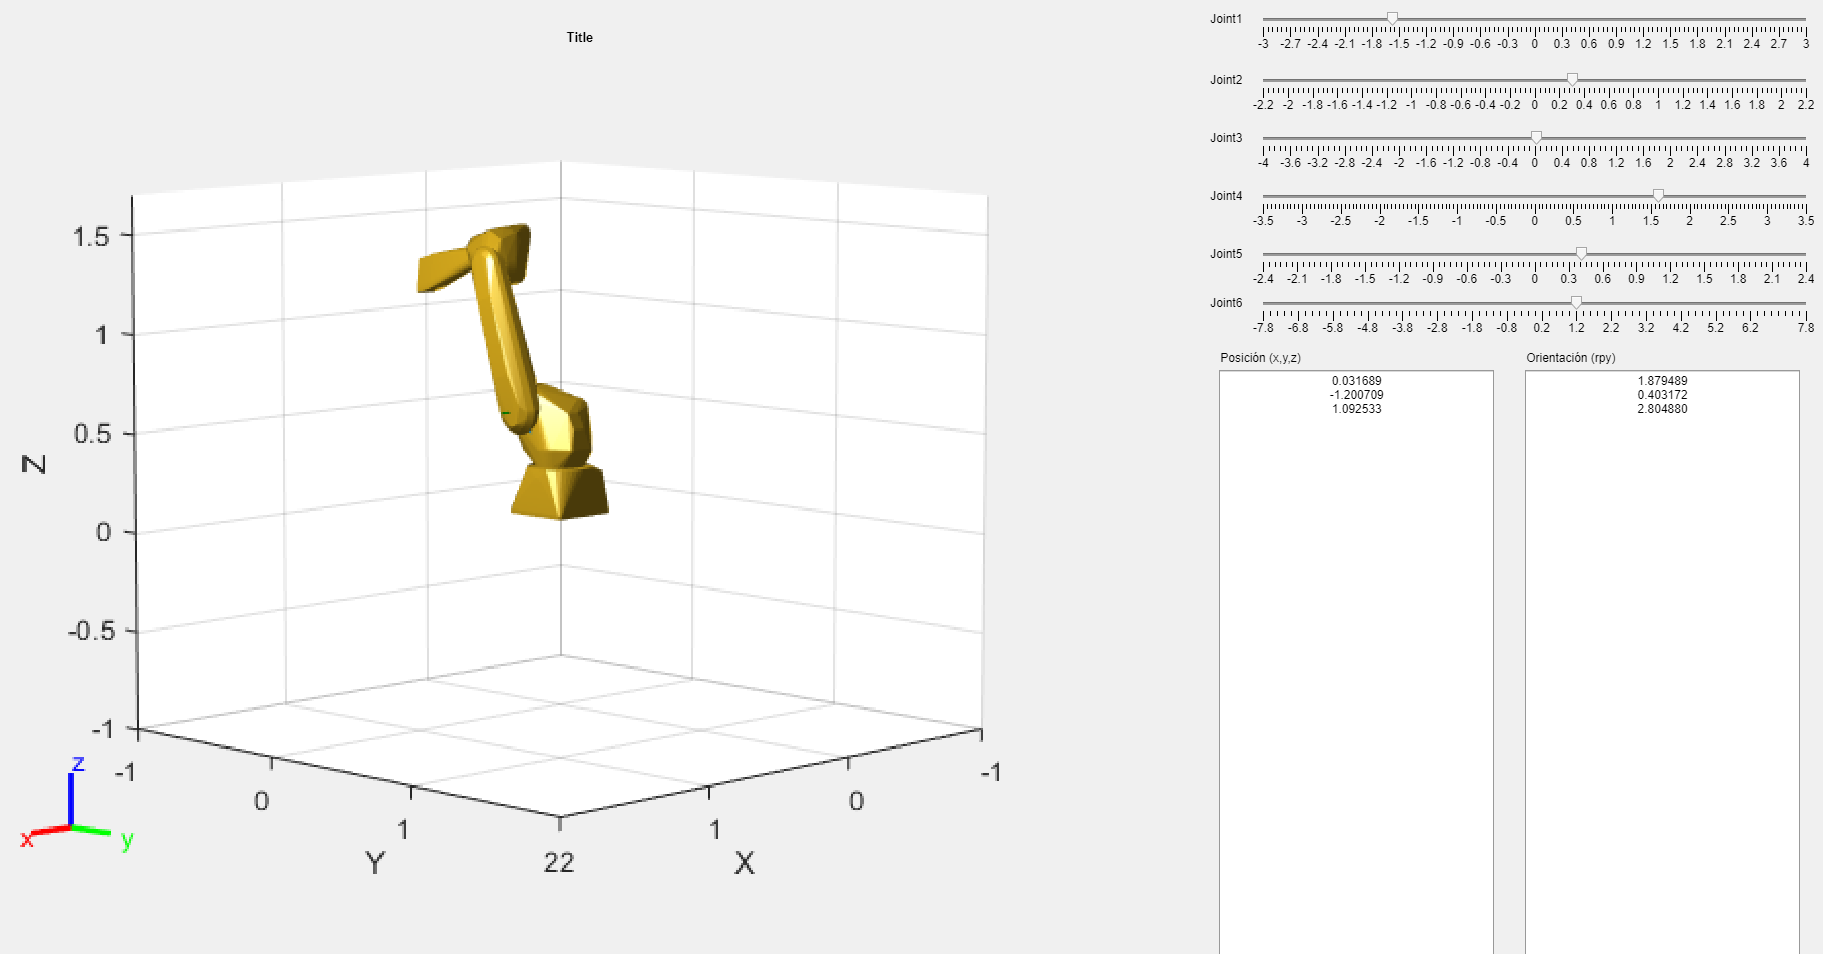

Figura 3. Verificación punto 2

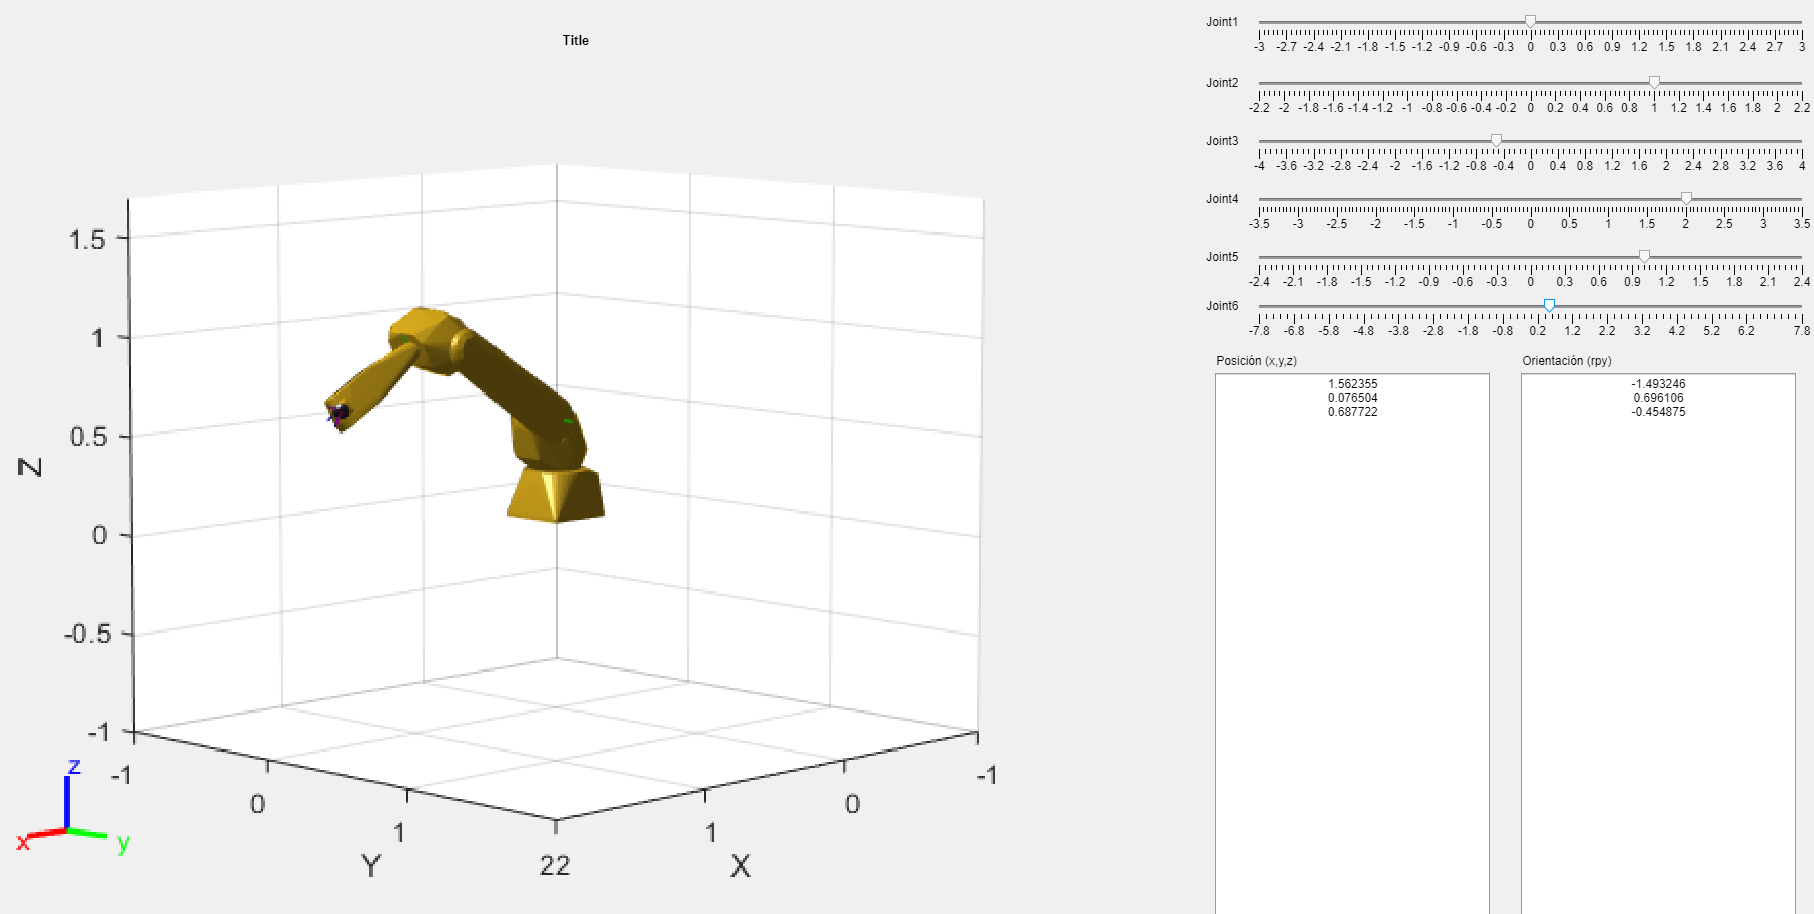

Figura 4. Verificación punto 3

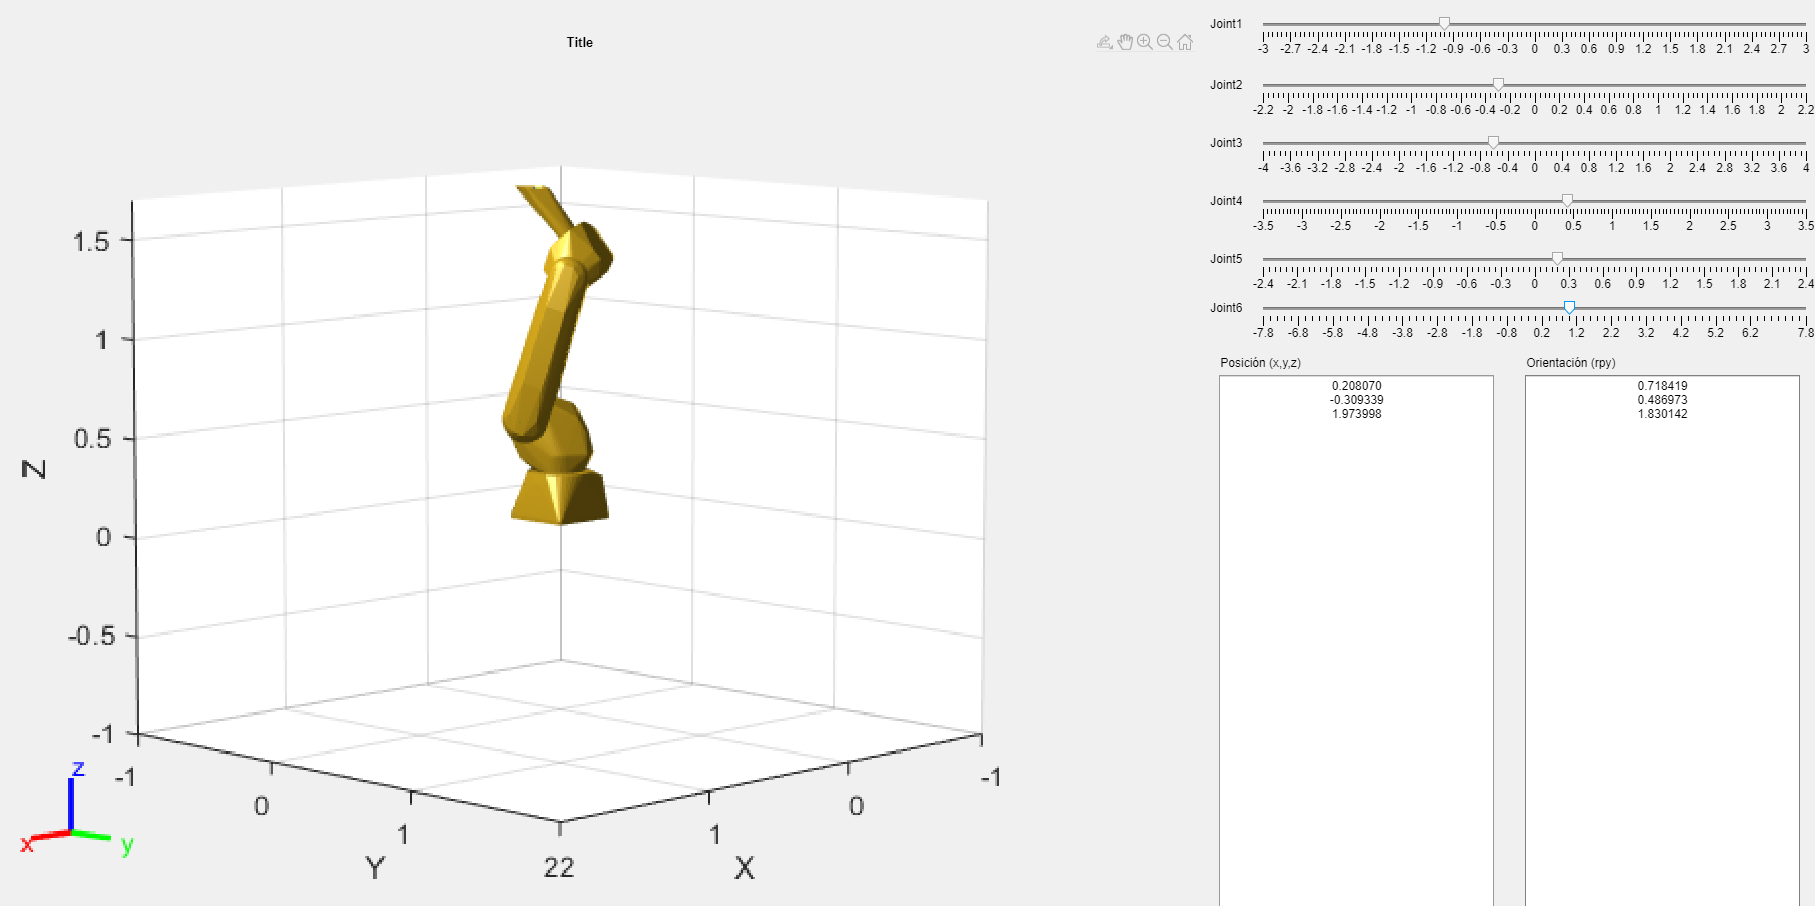

Figura 5. Verificación punto 4